## **Вариант 8**

## **Задание 1. Одноканальная система в форме вход-выход**

a2 = 9;
a1 = 26;
a0 = 24;
b2 = 2;
b1 = 6;
b0 = 8;

mdl = "task1";
open_system(mdl);

simIn = Simulink.SimulationInput(mdl);

out1 = sim(simIn);

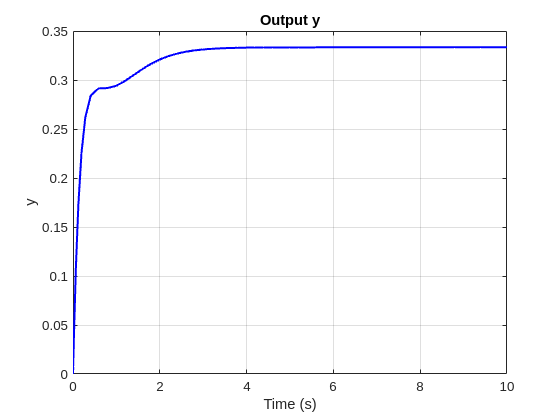

res = get(out1, "yout");
y = res{1};
u = res{2};

% Получение времени симуляции
t = out1.tout;

% Построение графика
figure;

% Первый сабплот: y1 и y2
plot(t, y.Values.Data, 'b-', 'LineWidth', 1.5); hold on;
% plot(t, u.Values.Data, 'r--', 'LineWidth', 1.5);
grid on;
xlabel('Time (s)');
ylabel('y');
title('Output y');
% legend('y', 'u', 'Location', 'northwest');
hold off;

## Задание 2. Переход от формы вход-выход к форме вход-состояние-выход

mdl = "task1_ctrl";
open_system(mdl);
simIn = Simulink.SimulationInput(mdl);
out2 = sim(simIn);

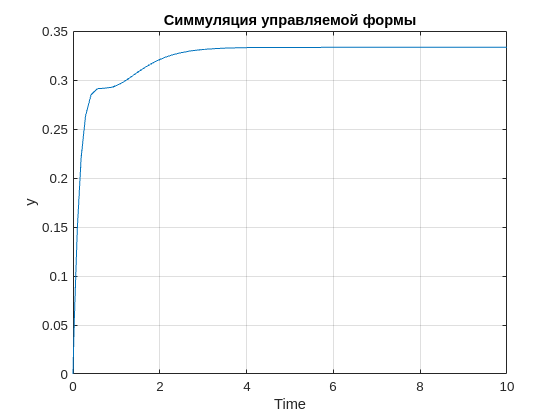

res = get(out2, "yout");
y = res{1};
plot(y.Values.Time, y.Values.Data)
grid on
xlabel("Time")
ylabel("y")
title("Симмуляция управляемой формы")

mdl = "task1_wtch";
open_system(mdl);
simIn = Simulink.SimulationInput(mdl);
out3 = sim(simIn);

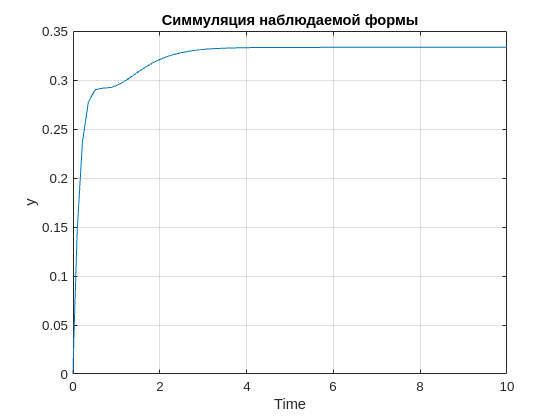

res = get(out3, "yout");
y = res{1};
plot(y.Values.Time, y.Values.Data)
grid on
xlabel("Time")
ylabel("y")
title("Симмуляция наблюдаемой формы")

mdl = "task1_diag";
open_system(mdl);
simIn = Simulink.SimulationInput(mdl);
out4 = sim(simIn);

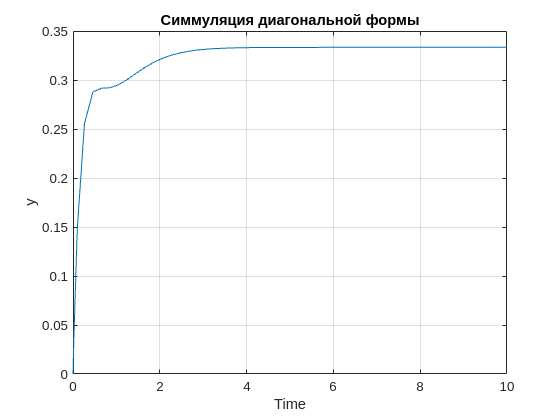

res = get(out4, "yout");
y = res{1};
plot(y.Values.Time, y.Values.Data)
grid on
xlabel("Time")
ylabel("y")
title("Симмуляция диагональной формы")

## `Задание 3.Многоканальная система в форме вход-выход`

mdl = "task3";
open_system(mdl);
simIn = Simulink.SimulationInput(mdl);
out30 = sim(simIn);

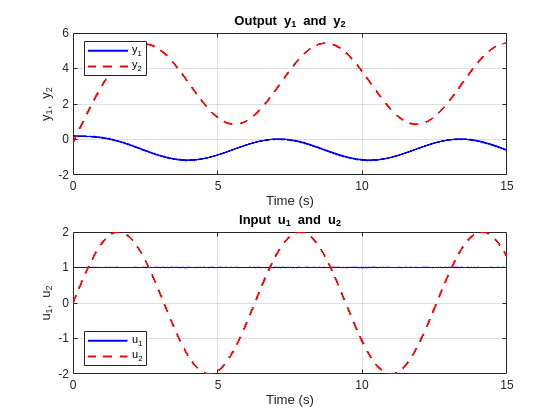

res = get(out30, "yout");
y1 = res{1};
y2 = res{2};
u1 = res{3};
u2 = res{4};

% Получение времени симуляции
t = out30.tout;

% Построение графика с двумя сабплотами
figure;

% Первый сабплот: y1 и y2
subplot(2, 1, 1); 
plot(t, y1.Values.Data, 'b-', 'LineWidth', 1.5); hold on;
plot(t, y2.Values.Data, 'r--', 'LineWidth', 1.5);
grid on;
xlabel('Time (s)');
ylabel('y_1, y_2');
title('Output y_1 and y_2');
legend('y_1', 'y_2', 'Location', 'northwest');
hold off;

% Третий сабплот: u1 и u2
subplot(2, 1, 2); 
plot(t, u1.Values.Data, 'b-', 'LineWidth', 1.5); hold on;
plot(t, u2.Values.Data, 'r--', 'LineWidth', 1.5);
grid on;
xlabel('Time (s)');
ylabel('u_1, u_2');
title('Input u_1 and u_2');
legend('u_1', 'u_2', 'Location', 'southwest');
hold off;

## `Задание 4. Многоканальная система в форме вход-состояние-выход`

mdl = "task4";
open_system(mdl);
simIn = Simulink.SimulationInput(mdl);
out40 = sim(simIn);

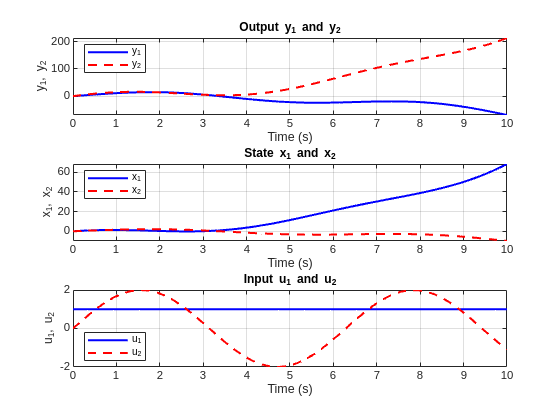

res = get(out40, "yout");
y1 = res{1};
y2 = res{2};
x1 = res{3};
x2 = res{4};
u1 = res{5};
u2 = res{6};

% Получение времени симуляции
t = out40.tout;

% Построение графика с двумя сабплотами
figure;

% Первый сабплот: y1 и y2
subplot(3, 1, 1); 
plot(t, y1.Values.Data, 'b-', 'LineWidth', 1.5); hold on;
plot(t, y2.Values.Data, 'r--', 'LineWidth', 1.5);
grid on;
xlabel('Time (s)');
ylabel('y_1, y_2');
title('Output y_1 and y_2');
legend('y_1', 'y_2', 'Location', 'northwest');
hold off;

% Второй сабплот: x1 и x2
subplot(3, 1, 2); 
plot(t, x1.Values.Data, 'b-', 'LineWidth', 1.5); hold on;
plot(t, x2.Values.Data, 'r--', 'LineWidth', 1.5);
grid on;
xlabel('Time (s)');
ylabel('x_1, x_2');
title('State x_1 and x_2');
legend('x_1', 'x_2', 'Location', 'northwest');
hold off;

% Третий сабплот: u1 и u2
subplot(3, 1, 3); 
plot(t, u1.Values.Data, 'b-', 'LineWidth', 1.5); hold on;
plot(t, u2.Values.Data, 'r--', 'LineWidth', 1.5);
grid on;
xlabel('Time (s)');
ylabel('u_1, u_2');
title('Input u_1 and u_2');
legend('u_1', 'u_2', 'Location', 'southwest');
hold off;